# Create Incremental Learner Without Any Prior Information

Create a default incremental linear model for regression.

Mdl = incrementalRegressionLinear()

Mdl =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [1×2 table]
    ResponseTransform: 'none'
                 Beta: [0×1 double]
                 Bias: 0
              Learner: 'svm'


  Properties, Methods


Mdl.EstimationPeriod

ans = 1000

`Mdl` is an `incrementalRegressionLinear` model object. All its properties are read-only.

`Mdl` must be fit to data before you can use it to perform any other operations. The software sets the estimation period to 1000 because half the width of the epsilon insensitive band `Epsilon` is unknown. You can set `Epsilon` to a positive floating-point scalar by using the `Epsilon` name-value argument. This action results in a default estimation period of 0.

Load the robot arm data set.

load robotarm

For details on the data set, enter `Description` at the command line.

Fit the incremental model to the training data by using the `updateMetricsAndFit` function. To simulate a data stream fit the model in chunks of 50 observations at a time. At each iteration:

- Process 50 observations.

- Overwrite the previous incremental model with a new one fitted to the incoming observations.

- Store $\beta_1$, the cumulative metrics, and the window metrics to see how they evolve during incremental learning.

% Preallocation
n = numel(ytrain);
numObsPerChunk = 50;
nchunk = floor(n/numObsPerChunk);
ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta1 = zeros(nchunk,1);    

% Incremental fitting
rng("default"); % For reproducibility
for j = 1:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend;    
    Mdl = updateMetricsAndFit(Mdl,Xtrain(idx,:),ytrain(idx));
    ei{j,:} = Mdl.Metrics{"EpsilonInsensitiveLoss",:};
    beta1(j + 1) = Mdl.Beta(1);
end

`IncrementalMdl` is an `incrementalRegressionLinear` model object trained on all the data in the stream. While `updateMetricsAndFit` processes the first 1000 observations, it stores the response values to estimate `Epsilon`; the function does not fit the coefficients until after this estimation period. During incremental learning and after the model is warmed up, `updateMetricsAndFit` checks the performance of the model on the incoming observations, and then fits the model to those observations.

To see how the performance metrics and $\beta_1$ evolve during training, plot them on separate tiles.

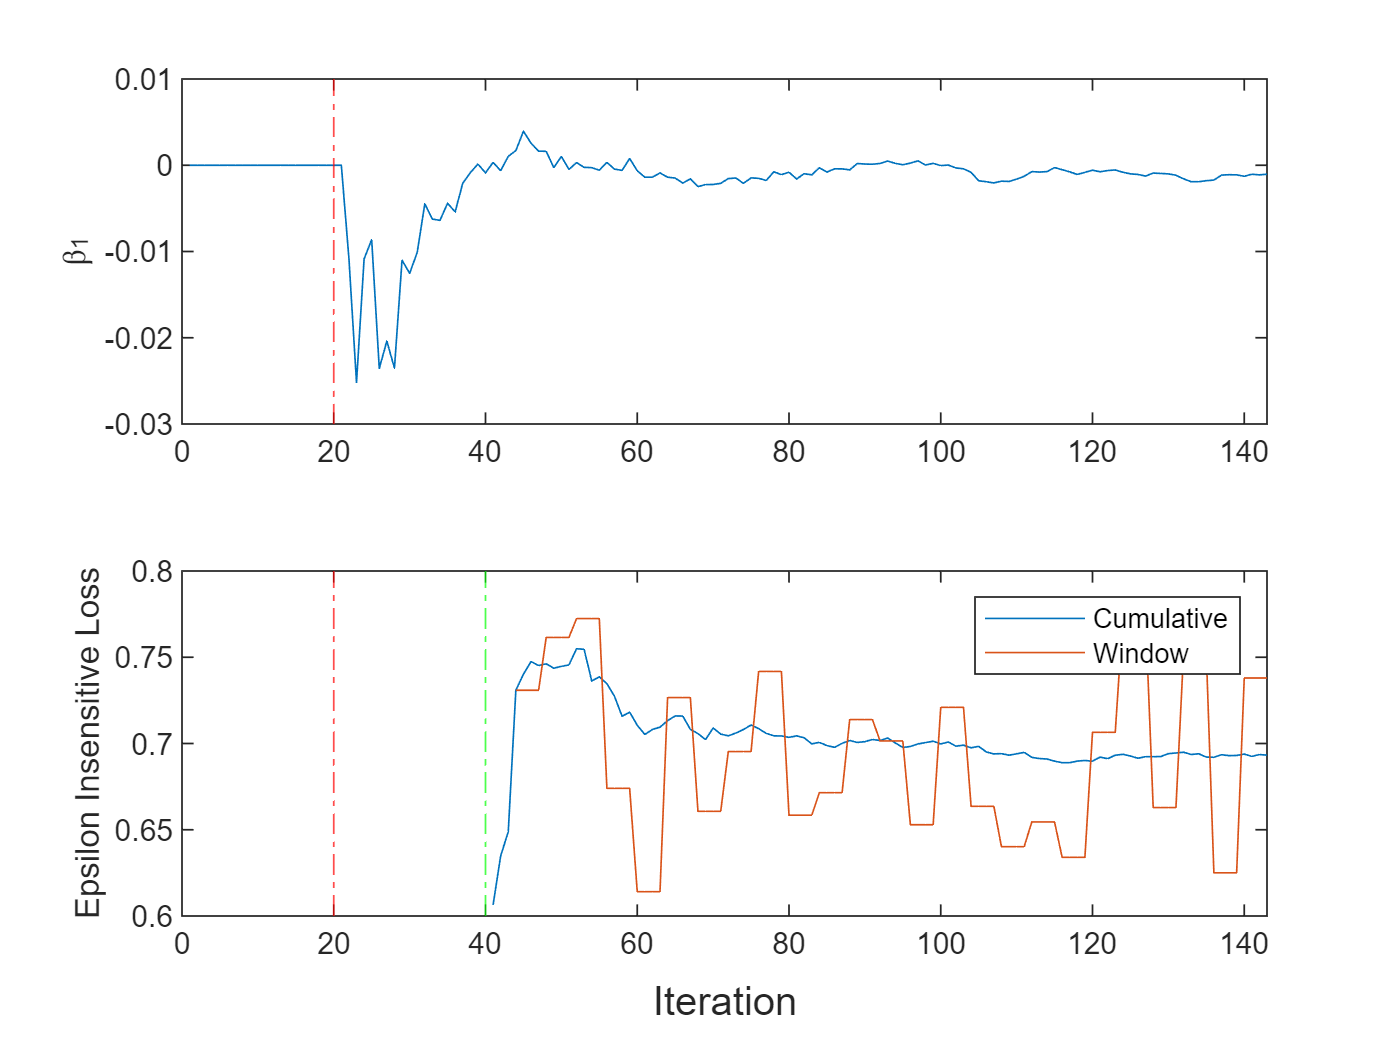

t = tiledlayout(2,1);
nexttile
plot(beta1)
ylabel('\beta_1')
xlim([0 nchunk])
xline(Mdl.EstimationPeriod/numObsPerChunk,'r-.')
nexttile
h = plot(ei.Variables);
xlim([0 nchunk])
ylabel('Epsilon Insensitive Loss')
xline(Mdl.EstimationPeriod/numObsPerChunk,'r-.')
xline((Mdl.EstimationPeriod + Mdl.MetricsWarmupPeriod)/numObsPerChunk,'g-.')
legend(h,ei.Properties.VariableNames)
xlabel(t,'Iteration')

The plot suggests that `updateMetricsAndFit` does the following:

- After the estimation period (first 20 iterations), fit $\beta_1$ during all incremental learning iterations.

- Compute the performance metrics after the metrics warm-up period only.

- Compute the cumulative metrics during each iteration.

- Compute the window metrics after processing 500 observations (4 iterations).

*Copyright 2020 The MathWorks, Inc.*